clc; clear; close all;

L = sym(1)

$$L = 1$$

C = 27

C =     27


k = sym(0.005);
D = sym(transpose(0:k:1));

phi_sym = @(x) sin(sym(pi*x))

phi_sym = function_handle with value:
    @(x)sin(sym(pi*x))



d = 10; % degree of interpolation
D_l = D(1:d); % left side of mesh on domain of function
D_r = D(end-d+1:end); % right side of mesh on domain of function
phi_D_l = phi_sym(D_l); % phi values on left side of mesh
phi_D_r = phi_sym(D_r); % phi values on right side of mesh

D_C = sym(transpose(L+k:k:L+C*k)); % vector of only continuation points domain
D_l_C = D_l + D_C(end) + k; % left side of mesh of next periods domain after continuation, has values of phi_D_l

D_interpolant = [D_r;D_l_C]; % mesh used for interpolation
phi_interpolant = [phi_D_r; phi_D_l]; % function values used for interpolation
w = barycentric_weights(D_interpolant); % barycentric weights dependent on interpolation mesh

phi_C = double(barycentric_compute_func(w, D_interpolant, phi_interpolant, D_C)) % continuation values using barycentric interpolation

phi_C =     -1.570647439067867e-02
    -3.140317312434709e-02
    -4.706936567881884e-02
    -6.266013434377415e-02
    -7.809042177004680e-02
    -9.321865535117801e-02
    -1.078343407305019e-01
    -1.216541393628410e-01
    -1.343298033437980e-01
    -1.454691612949613e-01


phi = @(x) sin(pi*x);
D = transpose(0:0.005:1);
phi_D = phi(D)

figure;
plot([D; double(D_C)], [phi_D; double(phi_C)])

D_FC = [D; double(D_C)];
phi_C

phi_C =     -1.570647439070220e-02
    -3.140317312451227e-02
    -4.706936567947119e-02
    -6.266013434564582e-02
    -7.809042177451714e-02
    -9.321865535979582e-02
    -1.078343407462985e-01
    -1.216541393875677e-01
    -1.343298033784470e-01
    -1.454691613433178e-01


phi_D

phi_D =                          0
     1.570731731182068e-02
     3.141075907812829e-02
     4.710645070964266e-02
     6.279051952931337e-02
     7.845909572784494e-02
     9.410831331851431e-02
     1.097343110910453e-01
     1.253332335643043e-01
     1.409012319375827e-01


phi_FC = [phi_D; phi_C];

% FFT Procedure
L_FC = D_FC(end) + 0.005 % new period after 1D-FC

L_FC =      1.140000000000000e+00


C_n = FFT_coeff(phi_FC) % ceofficients given by FFT

% Error Calculation
k_err = 0.005/20

k_err =      2.500000000000000e-04


D_err = transpose(0:k_err:1)

D_err =                          0
     2.500000000000000e-04
     5.000000000000000e-04
     7.500000000000000e-04
     1.000000000000000e-03
     1.250000000000000e-03
     1.500000000000000e-03
     1.750000000000000e-03
     2.000000000000000e-03
     2.250000000000000e-03


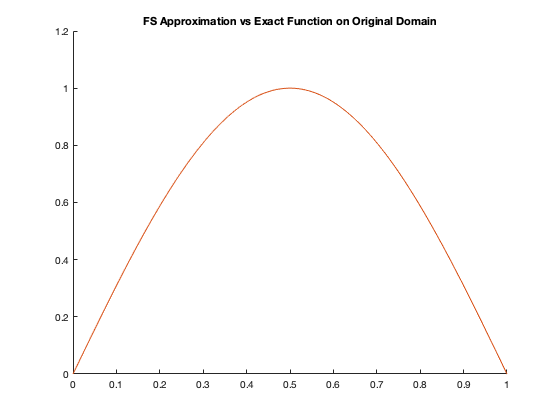

phi_FFT = FFT_compute_func(C_n, L_FC, D_err);
phi_exact = phi(D_err);

figure;
hold on;
plot(D_err, phi_exact)
plot(D_err, phi_FFT)
title("FS Approximation vs Exact Function on Original Domain")


err = max(abs(phi_FFT - phi_exact)) % max error on mesh

err =      1.279471203031318e-08
